# Math 244: MATLAB Assignment 5

### Name: 

### RUID:

### Date:

clear;
clc;

## 1. 

Ac = 1/5, As = 2, Af = -1/5, w = 1

## 2.

% Run secondundampedsolver with the appropriate coefficients
A = 3;
B = 1;
omegaf = 4;
y0 = 0;
v0 = 2;
[Ac, As, omegas, Af] = secondUndampedSolver(B, A, omegaf, y0, v0)

Ac = 0.2000

As = 2

omegas = 1

Af = -0.2000

## 3.

% Coefficients 1
A = 1;
B = 9;
omegaf = 4;
y0 = 0;
v0 = 0;
[Ac, As, omegas, Af] = secondUndampedSolver(B, A, omegaf, y0, v0)

Ac = 0.1429

As = 0

omegas = 3

Af = -0.1429

% Coefficients 2
A = 1;
B = 9;
omegaf = 3.1;
y0 = 0;
v0 = 0;
[Ac, As, omegas, Af] = secondUndampedSolver(B, A, omegaf, y0, v0)

Ac = 1.6393

As = 0

omegas = 3

Af = -1.6393

% Coefficients 3
A = 1;
B = 9;
omegaf = 3.01;
y0 = 0;
v0 = 0;
[Ac, As, omegas, Af] = secondUndampedSolver(B, A, omegaf, y0, v0)

Ac = 16.6389

As = 0

omegas = 3

Af = -16.6389

% Coefficients 4
A = 1;
B = 9;
omegaf = 3;
y0 = 0;
v0 = 0;
[Ac, As, omegas, Af] = secondUndampedSolver(B, A, omegaf, y0, v0)

Ac = -Inf

As = 0

omegas = 3

Af = Inf


%The amplitudes keep decreasing as omegaf reaches 3. This means that
%resonance is reached at 3 and the amplitude goes to negative infinity.

## 4.

y(t) = t/6 sin(3t)

The function expects the solution to Acos(ωt)+Bsin(ωt) with A and B as constants. Since we have t as a coefficient, the function ceases to work properly.

## 5.

syms y(t);
Dy = diff(y);

ode = diff(y,t,2) + 9*y == cos(3*t);
cond1 = y(0) == 0;
cond2 = Dy(0) == 0;

conds = [cond1 cond2];
ySol(t) = dsolve(ode,conds);
ySol = simplify(ySol)

$$ySol(t) = \frac{t\,\sin\left(3\,t\right)}{6}$$

## 6.

tVals = linspace(0,2, 2*8192);

omega = 2300;

% Use second undamped solver to get the coefficients
A = (2400-omega)*2400;
B = 2400^2;
y0 = 0;
v0 = 0;
[Ac, As, omegas, Af] = secondUndampedSolver(B, A, omega, y0, v0)

Ac = -0.5106

As = 0

omegas = 2400

Af = 0.5106

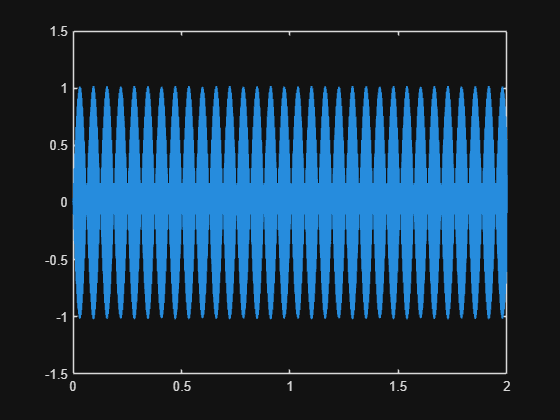


% Put the coefficients together in an anonymous function
sol1 = @(t) Ac*cos(omegas*t) + As*sin(omegas*t) + Af*cos(omega*t);

figure()
plot(tVals, sol1(tVals));


%sound(sol1(tVals));

omega = 2350;


% Repeat for this new omega 
A = (2400-omega)*2400;
B = 2400^2;
y0 = 0;
v0 = 0;
[Ac, As, omegas, Af] = secondUndampedSolver(B, A, omega, y0, v0)

Ac = -0.5053

As = 0

omegas = 2400

Af = 0.5053

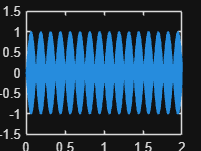


% Put the coefficients together in an anonymous function
sol1 = @(t) Ac*cos(omegas*t) + As*sin(omegas*t) + Af*cos(omega*t);

figure()
plot(tVals, sol1(tVals));


%sound(sol1(tVals));

omega = 2395;

% Repeat for this new omega 
A = (2400-omega)*2400;
B = 2400^2;
y0 = 0;
v0 = 0;
[Ac, As, omegas, Af] = secondUndampedSolver(B, A, omega, y0, v0)

Ac = -0.5005

As = 0

omegas = 2400

Af = 0.5005

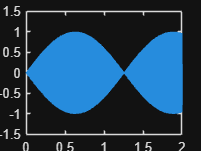


% Put the coefficients together in an anonymous function
sol1 = @(t) Ac*cos(omegas*t) + As*sin(omegas*t) + Af*cos(omega*t);

figure()
plot(tVals, sol1(tVals));


%sound(sol1(tVals));

The frequency decreases as w approaches 2400.

## 7. 

syms y1(t);
Dy1 = diff(y1);

ode1 = diff(y1,t,2) + diff(y1,t,1) +16*y1 == 0;
cond1 = y1(0) == 10;
cond2 = Dy1(0) == 0;

conds = [cond1 cond2];
ySol1(t) = dsolve(ode1,conds);
ySol1 = simplify(ySol1);

syms y2(t);
% Copy the previous code, changing all references to y1 and ySol1 to y2 and
% ySol2.
Dy2 = diff(y2);

ode2 = diff(y2,t,2) + 10*diff(y2,t,1) +16*y2 == 0;
cond1 = y2(0) == 10;
cond2 = Dy2(0) == 0;

conds = [cond1 cond2];
ySol2(t) = dsolve(ode2,conds);
ySol2 = simplify(ySol2);


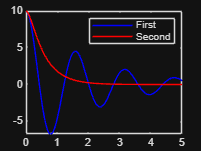

figure(5);
fplot(ySol1, [0,5],'b');
hold on;
fplot(ySol2, [0,5],'r');
legend('First', 'Second');
hold off;

The first is the pendulum swinging through water, as the pendulum is able to swing a few times given water's lower viscosity compared to molasses. The second graph is the pendulum swigning through molasses, since the viscosity prevents it from completing a single oscillation.

function [Ac, As, omegas, Af] = secondUndampedSolver(B, A, omegaf, y0, v0)

    Af = A/(B - omegaf^2);
    Ac = y0-Af;
    omegas = sqrt(B);
    As = v0/omegas;
    
end